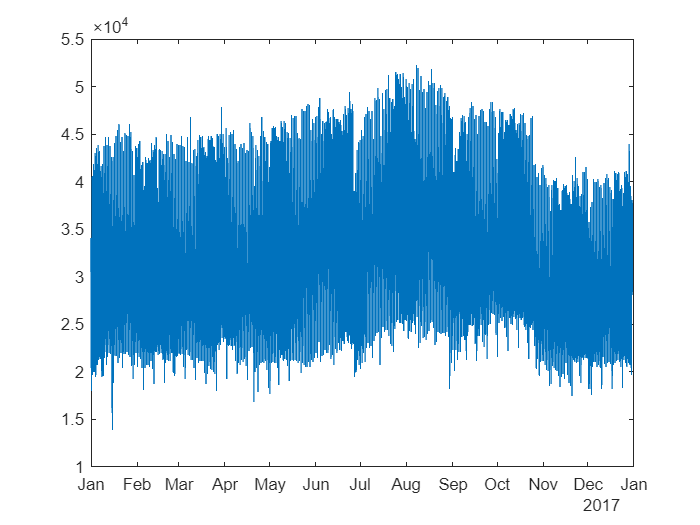

% Datetime Correction(Messy Format)
Start_time = datetime(2017,1,1,0,0,0);
End_time = datetime(2017,12,30,23,50,0);
Date_time = (Start_time:minutes(10):End_time)';

data_being_processed = removevars(TetuanCitypowerconsumption2017,"DateTime");
data_being_processed = addvars(data_being_processed,Date_time,'NewVariableNames',"DateTime", 'Before',"Temperature" );
%data_being_processed.Zone1PowerConsumption = data_being_processed.Zone1PowerConsumption+data_being_processed.Zone2PowerConsumption+data_being_processed.Zone3PowerConsumption;
plot(data_being_processed.DateTime, data_being_processed.Zone1PowerConsumption)

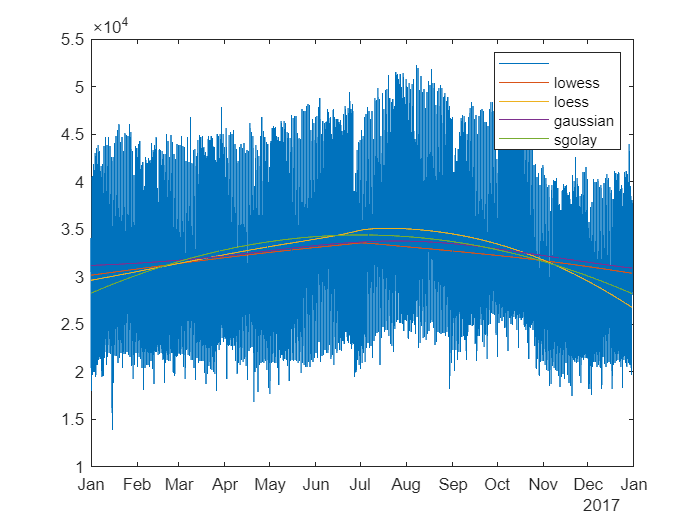

hold on

trend = smoothdata(data_being_processed.Zone1PowerConsumption, "lowess","SmoothingFactor",1);
plot(Date_time, trend)
trend = smoothdata(data_being_processed.Zone1PowerConsumption, "loess","SmoothingFactor",1);
plot(Date_time, trend)
trend = smoothdata(data_being_processed.Zone1PowerConsumption, "gaussian","SmoothingFactor",1);
plot(Date_time, trend)
trend = smoothdata(data_being_processed.Zone1PowerConsumption, "sgolay","SmoothingFactor",1);
plot(Date_time, trend)
hold off
legend([" " "lowess" "loess" "gaussian" "sgolay"])

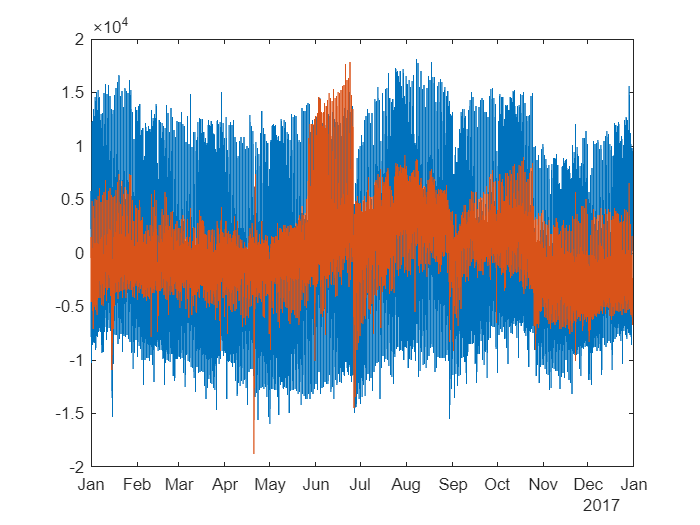


de_trend_using_smoothing = data_being_processed.Zone1PowerConsumption - trend;
plot(Date_time, de_trend_using_smoothing)
de_trend_using_detrend_function = detrend(data_being_processed.Zone1PowerConsumption);
hold on
% plot(Date_time, de_trend_using_detrend_function)
hold off
correlation_coefficient = corrcoef(de_trend_using_smoothing,de_trend_using_detrend_function);
seasonality_period = 6*24*7;
sidx = cell(seasonality_period,1);
for i = 1:seasonality_period
 sidx{i,1} = i:seasonality_period:52416; 
end
seasonality_component_for_seasonality_period = cellfun(@(x) mean(de_trend_using_detrend_function(x)),sidx);
complete_years = floor(size(data_being_processed,1)/seasonality_period);    % Num. complete years
seasonality_component_complete = repmat(seasonality_component_for_seasonality_period,complete_years,1);
residual = de_trend_using_detrend_function-seasonality_component_complete;
hold on
plot(Date_time, residual)
hold off
ylim([-2e+4 2e+4])

adftest(residual)

ans = logical
   1


adftest(seasonality_component_complete)

ans = logical
   1
